clear all;

# Exercice 4 : Filtre Médian

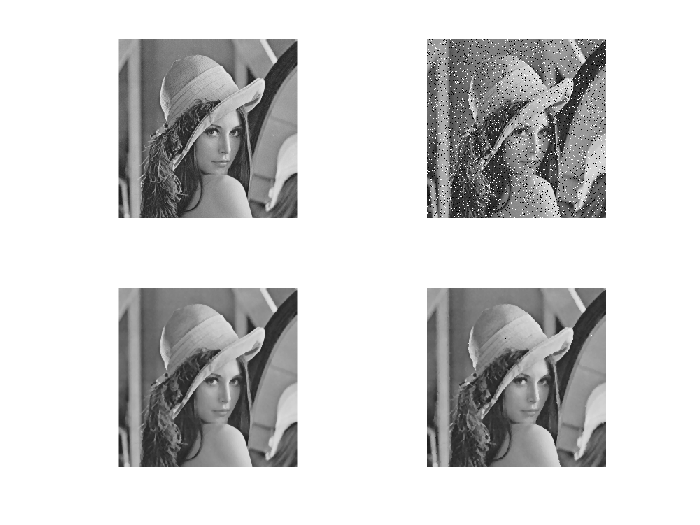


I = imread("lena.tif");

IB = imnoise(I, 'salt & pepper', 0.1);
IMedian = AppliquerFiltreMedian(I);
IBMedian = AppliquerFiltreMedian(IB);

%Affichage en bloc de 2x2
figure
subplot(2, 2, 1);
imshow(I);
subplot(2, 2, 2);
imshow(IB);
subplot(2, 2, 3);
imshow(IMedian);
subplot(2, 2, 4);
imshow(IBMedian);

# Exercice 5 : Erosion - Dilatation

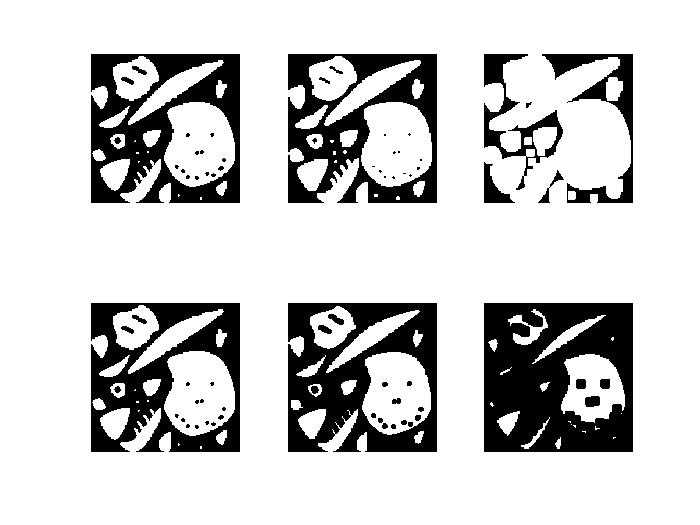

M = imread("Morpho.tif");
%M = I;

MD = Dilat(M, 1);
MD5 = Dilat(M, 5);
ME = Erod(M,1);
ME5 = Erod(M,5);

%Affichage en bloc de 2x3
figure
subplot(2, 3, 1);
imshow(M);%Image source
subplot(2, 3, 2);
imshow(MD);%image dilatée
subplot(2, 3, 3);
imshow(MD5);%image dilatée 5 fois
subplot(2, 3, 4);
imshow(M);
subplot(2, 3, 5);
imshow(ME);
subplot(2, 3, 6);
imshow(ME5);

# Exercice 6 : Ouverture - Fermeture

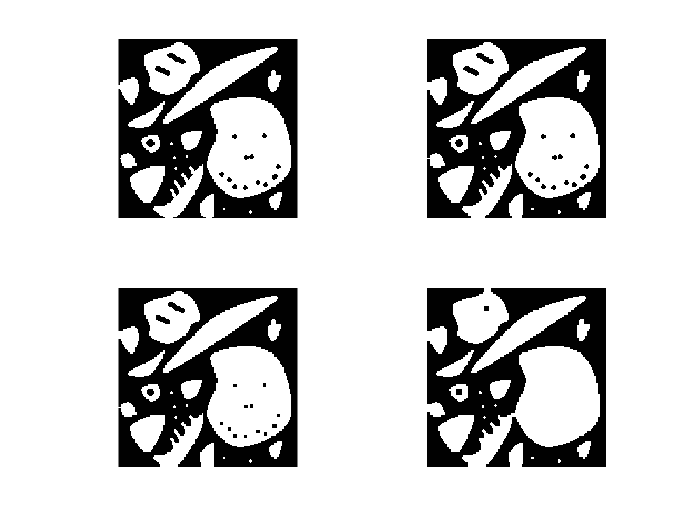



%Affichage en bloc de 2x2 des fermetures
figure
subplot(2, 2, 1);
imshow(M);
subplot(2, 2, 2);
imshow(Fermeture(M,1));
subplot(2, 2, 3);
imshow(Fermeture(M,2));
subplot(2, 2, 4);
imshow(Fermeture(M,3));

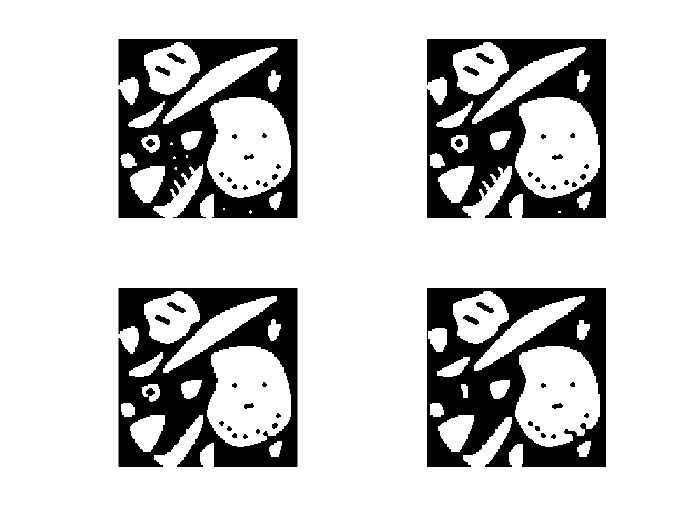


%Affichage en bloc de 2x2 des ouvertures
figure
subplot(2, 2, 1);
imshow(M);
subplot(2, 2, 2);
imshow(Ouverture(M,1));
subplot(2, 2, 3);
imshow(Ouverture(M,2));
subplot(2, 2, 4);
imshow(Ouverture(M,3));

# Exercice 7 : Filtrage Morphologique

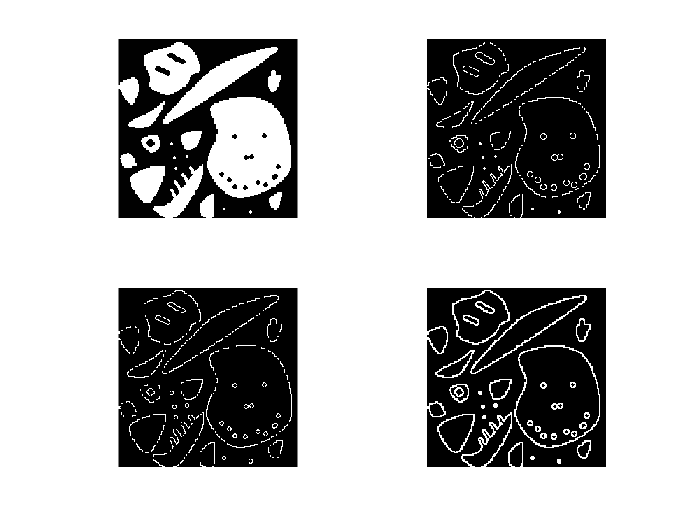

MGext = GradientExterne(M);
MGint = GradientInterne(M);

%Affichage en bloc de 2x2 des Gradiants
figure
subplot(2, 2, 1);
imshow(M);
subplot(2, 2, 2);
imshow(MGint);
subplot(2, 2, 3);
imshow(MGext);
subplot(2, 2, 4);
imshow(MGint + MGext);

# Exercice 8 : Dilatation Géodésique

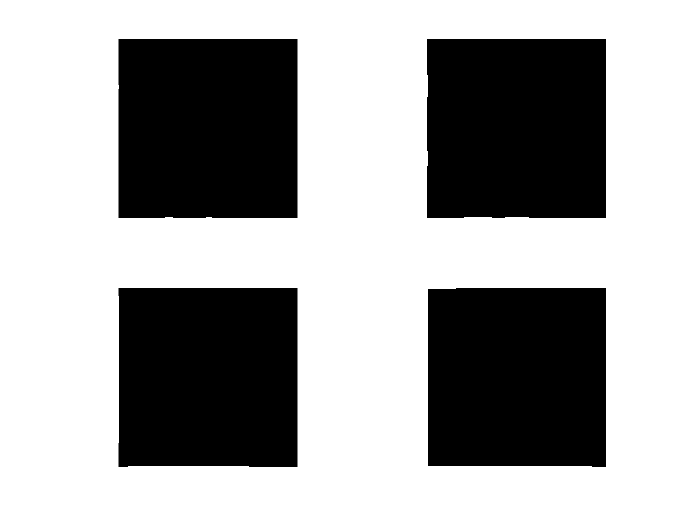

%Création du cadre
cadre = zeros(256,256,'uint8');
cadre(1,:)=255;
cadre(:,1)=255;
cadre(256,:)=255;
cadre(:,256)=255;

%Début du cadre
Dgeo=min(M,cadre);

figure
subplot(2,2,1);
imshow(Dgeo);
subplot(2,2,2);
imshow(DilatGeodesique(M,cadre,10));
subplot(2,2,3);
imshow(DilatGeodesique(M,cadre,50));
subplot(2,2,4)
imshow(DilatGeodesique(M,cadre,100));

function R = AppliquerFiltreMedian(I)

R  = I;
[nbC, nbL] = size(I);
voisin = zeros(3,3);

%Application du filtre Median
for i = 2:nbC-1
    for j = 2:nbL-1         
        voisin = [I(i-1,j-1) I(i-1,j) I(i-1,j+1); I(i,j-1) I(i,j) I(i,j+1); I(i+1,j-1) I(i+1,j) I(i+1,j+1)];
        Res = sort(double(voisin(:)));
        R(i,j) = Res(5);
    end
end

%Recopie des bords
R(1,:) = R(2,:);
R(nbC,:) = R(nbC-1,:);
R(:,1) = R(:,2);
R(:,nbL) = R(:,nbL-1);

return;

end

function R = Dilat(I, lambda)

R  = I;
[nbC, nbL] = size(I);
voisin = zeros(3,3);

for k = 1:lambda
    %Application du filtre Median
    for i = 2:nbC-1
        for j = 2:nbL-1         
            voisin = [I(i-1,j-1) I(i-1,j) I(i-1,j+1); I(i,j-1) I(i,j) I(i,j+1); I(i+1,j-1) I(i+1,j) I(i+1,j+1)];
            Res = sort(double(voisin(:)));
            R(i,j) = Res(9);
        end
    end
    
    %Recopie des bords
    R(1,:) = R(2,:);
    R(nbC,:) = R(nbC-1,:);
    R(:,1) = R(:,2);
    R(:,nbL) = R(:,nbL-1);

    I=R;
    
end

return;

end

function R = Erod(I, lambda)

R  = I;
[nbC, nbL] = size(I);
voisin = zeros(3,3);

for k = 1:lambda
    %Application du filtre Median
    for i = 2:nbC-1
        for j = 2:nbL-1         
            voisin = [I(i-1,j-1) I(i-1,j) I(i-1,j+1); I(i,j-1) I(i,j) I(i,j+1); I(i+1,j-1) I(i+1,j) I(i+1,j+1)];
            Res = sort(double(voisin(:)));
            R(i,j) = Res(1);
        end
    end
    
    %Recopie des bords
    R(1,:) = R(2,:);
    R(nbC,:) = R(nbC-1,:);
    R(:,1) = R(:,2);
    R(:,nbL) = R(:,nbL-1);

    I=R;
    
end

return;

end

function R = Ouverture(I, lambda)

R=Erod(I, lambda);
R=Dilat(R, lambda);

end

function R = Fermeture(I, lambda)

R=Dilat(I, lambda);
R=Erod(R, lambda);

end

function R = GradientInterne(I) %image - érodé

R = I - Erod(I, 1);

end

function R = GradientExterne(I) %dilaté - image

R = Dilat(I, 1) - I;

end

function J = DilatGeodesique(I, K, lambda)

J  = I;
[nbC, nbL] = size(I);
voisin = zeros(3,3);

for k = 1:lambda
    %Application du filtre Median
    for i = 2:nbC-1
        for j = 2:nbL-1         
            voisin = [I(i-1,j-1) I(i-1,j) I(i-1,j+1); I(i,j-1) I(i,j) I(i,j+1); I(i+1,j-1) I(i+1,j) I(i+1,j+1)];
            Res = sort(double(voisin(:)));
            J(i,j) = Res(9);
        end
    end
    
    %Recopie des bords
    J(1,:) = J(2,:);
    J(nbC,:) = J(nbC-1,:);
    J(:,1) = J(:,2);
    J(:,nbL) = J(:,nbL-1);

    J = min(J, K);
    I=J;
    
end

return;

end